# Image Processing

## Create Complex Signal from Image

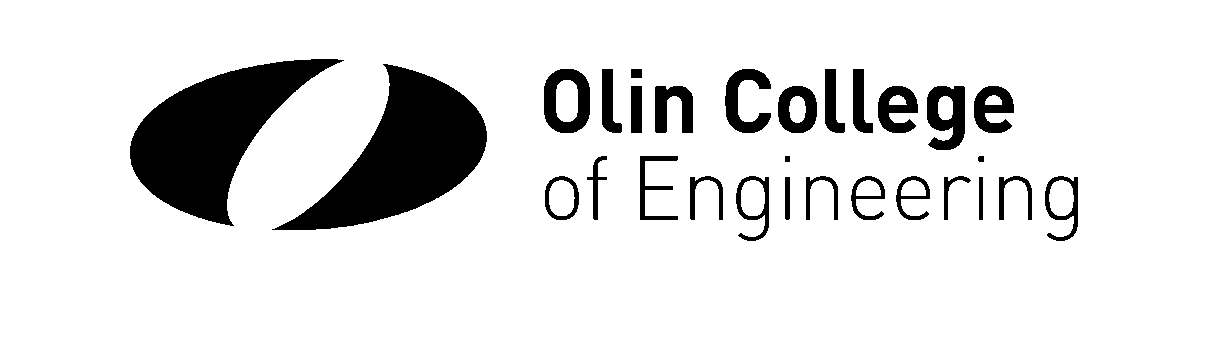

% Read in image and convert to black & white
raw = imread('olin_logo.png',"png");
bw = raw >= 128;
imshow(bw)


% Get size of picture and allocate space for column vector
sz = size(bw);
rows = sz(1);
cols = sz(2);
total = rows*cols;
bitlength = 16;
rowb = de2bi(rows,bitlength).'; % 16-bit binary
colsb = de2bi(cols,bitlength).'; %16-bit binary

% Turn image into column vector
data = bw(:);
data = [rowb.' colsb.' data.'].';
data(data == 0) = -1;

% Turn image data into complex signal
tx_data = zeros(ceil(length(data)/2),1);
for i = 1:2:length(data)
    if i == length(data) && mod(i,2) ~= 0
        tx_data(ceil(i/2)) = data(i) + 1i;
    else
        tx_data(ceil(i/2)) = data(i) + 1i*data(i+1);
    end
end

## Create Image from Complex Signal

% Read in received signal
rx_signal = tx_data;

% Create column vector from complex data
rx_data = zeros(length(rx_signal)*2,1);
for m = 1:2:length(rx_signal)*2
    rx_data(m) = real(rx_signal(ceil(m/2)));
    rx_data(m+1) = imag(rx_signal(ceil(m/2)));
end
rx_data(rx_data == -1) = 0;

% Get number of rows and columns in image
rx_rows = rx_data(1:bitlength);
rx_rows_count = bi2de(rx_rows.');
rx_cols = rx_data(bitlength+1:bitlength*2);
rx_cols_count = bi2de(rx_cols.');

% Create image from vector of data
rx_im_data = rx_data(bitlength*2+1:bitlength*2+rx_rows_count*rx_cols_count);
rx_image = reshape(rx_im_data, [rx_rows_count,rx_cols_count]);
imshow(rx_image)